%Number 1; n = 20
result = 0;
input = 20;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result = 10

%Number 2; n = 100
result = 0;
input = 100;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result = 50

f = @(x) 0.5*((x-1)).^2;
%Number 2; long format
format long;

f(sqrt(3))

ans =    0.267949192431123


% 0.267949192431123

%Number 2; short format
format short;

f(sqrt(3))

ans = 0.2679

%0.2679

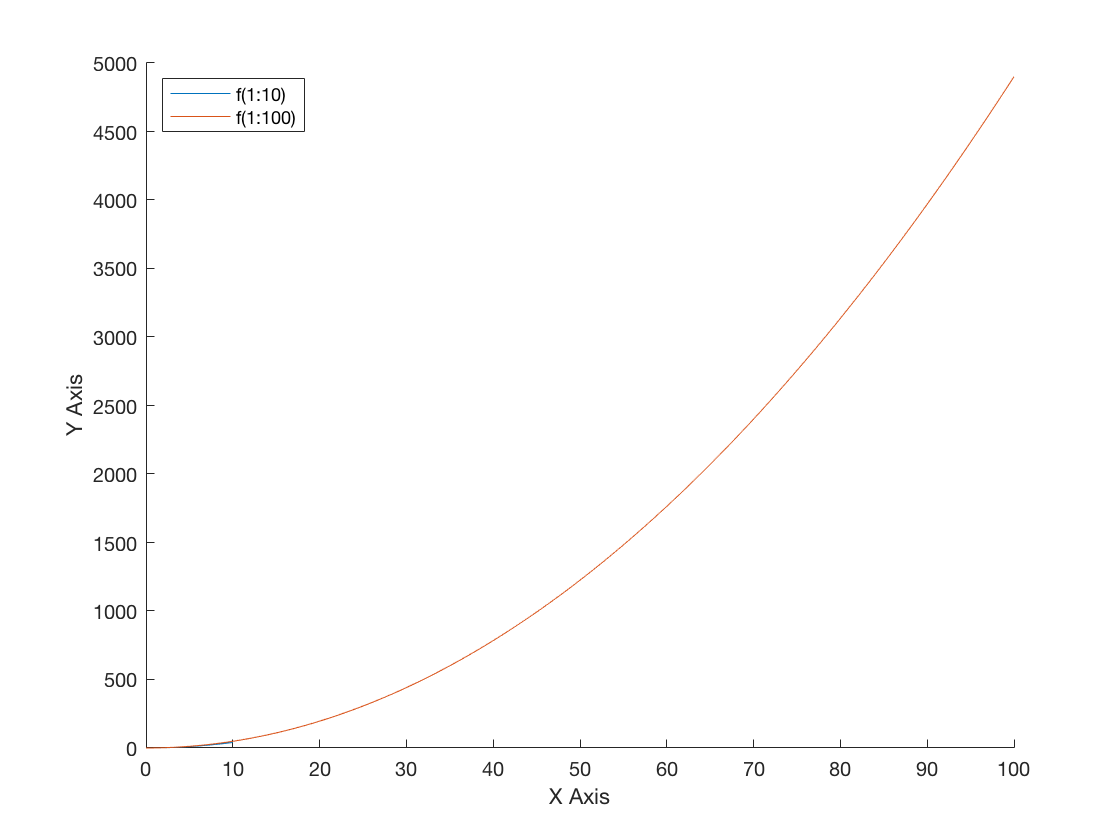

%Number 3 Plotting both functions on same graph
t = linspace(0,10,10);
t2 = linspace(0,100,100);
hold on
plot(t,f(1:10))
plot(t2,f(1:100))
legend({'f(1:10)','f(1:100)'},'Location','northwest');
xlabel("X Axis");
ylabel("Y Axis");
hold off

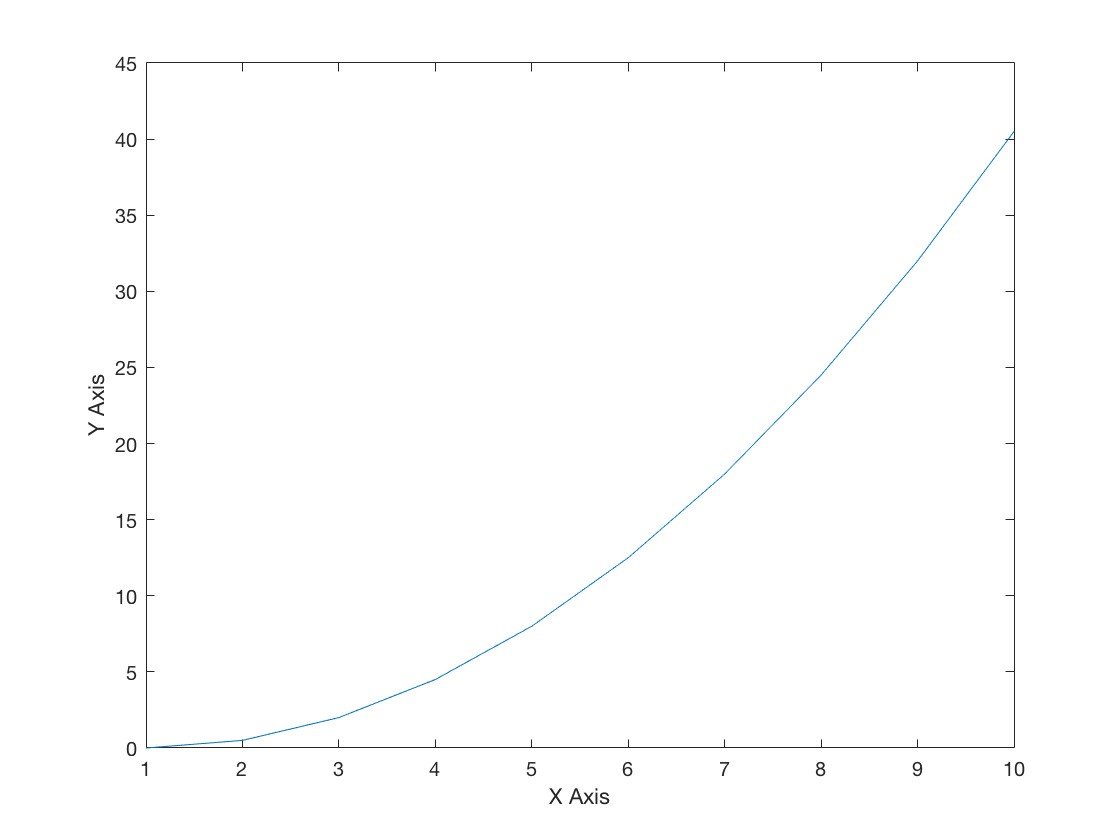

%Number 3; Input = 10
input = 10;
graphOne=(1:10);

for i = 1:input 
    graphOne(i) = f(i);
end
  plot(1:10, graphOne);
  xlabel("X Axis");
  ylabel("Y Axis");

%shorter version
% plot(1:10, f(1:10));

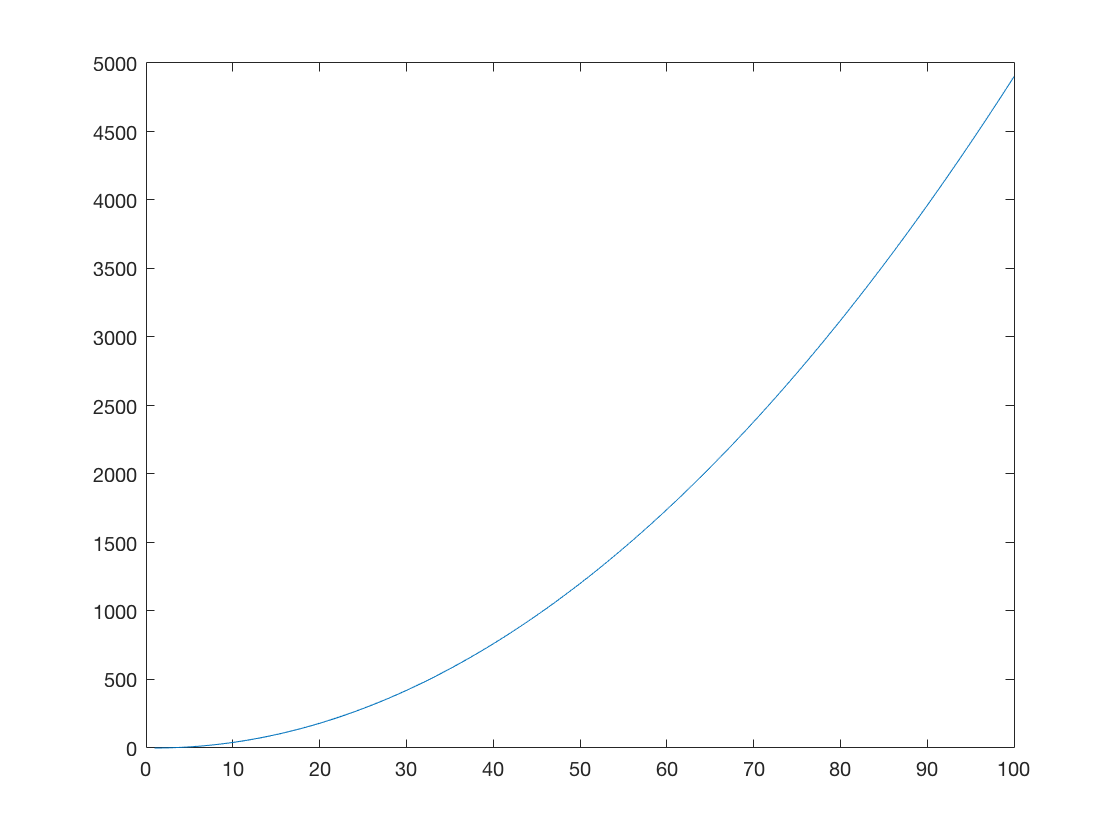

%Number 3; Input = 100
input = 100;
graphTwo=(1:100);
 
for i =1:input
    graphTwo(i) = f(i);
end
plot(1:100, graphTwo);

%shorter version
% plot(1:100, f(1:100));

%Number 4
h = @(x,h)(f(x+h)-f(x))/h;

h(1.1,0.1)

ans = 0.1500

h(1.1,0.01)

ans = 0.1050

h(1.1,0.001)

ans = 0.1005

%Number 5
x = 0:(99/100):1, f(0:99/100:1)

x =          0    0.9900


ans =     0.5000    0.0001


f = (0:99/100:1), h(0:99/100:1.1,0:99/100:1)

f =          0    0.9900


ans = 0.4850

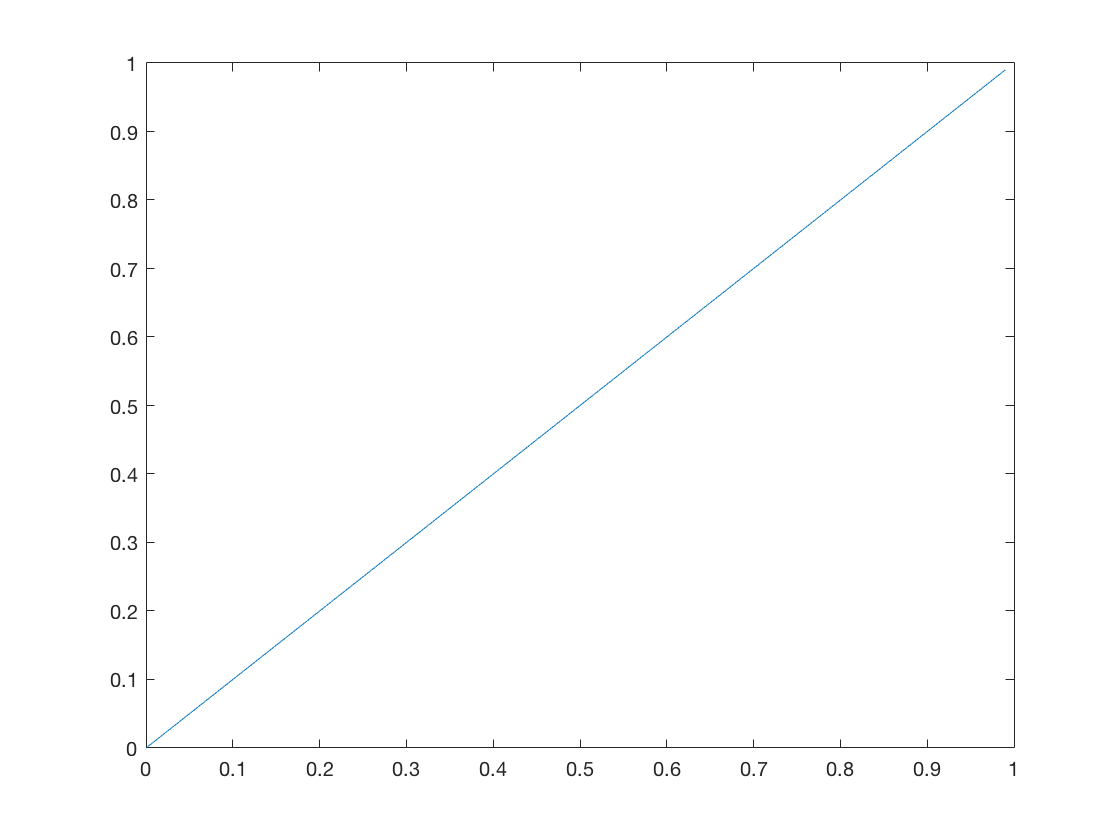

plot (x,f)